kappa_ext = .8873e6;
kappa_int = 1.238e6;
kappa_tot = kappa_ext + kappa_int;% 1.5e6; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
kerr = -.4647e6;
detunings = linspace(-15e6, 15e6, 201);
detuning_array = detunings; 
kerr_fluctuation_detuning = linspace(-10*abs(kerr), 10*abs(kerr), 401);
kerr_fluctuation_spacing = mean(diff(kerr_fluctuation_detuning));

omega_0 = 5.7849e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
plot_figures = 1;
input_attenuation = 82; 

power_input_start_dBm = -33 -input_attenuation; 
power_input_stop_dBm = -45 -input_attenuation; % input_attenuationdB is approx fridge attenuation. 
number_powers = 1;
power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);

% power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 5);
% power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);

power_input_in_dBm = linspace(power_input_start_dBm, power_input_stop_dBm, number_powers);
power_input_in_watts = 1e-3.*10.^(power_input_in_dBm/10);

power_input_in_numbers = power_input_in_watts/h/omega_0;
kerr = kerr/1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
power_input_in_numbers = power_input_in_numbers/1e6;
kerr_fluctuation_detuning = kerr_fluctuation_detuning/1e6;
kerr_fluctuation_spacing = kerr_fluctuation_spacing/1e6;
[detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
amp_roots = zeros([size(detunings_array),3]);

for i = 1: size(detunings_array,1)
    for j = 1: size(detunings_array,2)
        amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array(i,j)]);
    end
end
amp_roots(imag(amp_roots) ~=0) = NaN;
% amp_roots = real(amp_roots);

detunings_array_reps = repmat(detunings_array, [1, 1, 3]);

s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);

s11(amp_roots == 0) = NaN;

amp_roots = repmat(amp_roots, [1, 1, 1, length(kerr_fluctuation_detuning)]);
s11 = repmat(s11, [1, 1, 1, length(kerr_fluctuation_detuning)]);
kerr_fluctuation_detuning = repmat(kerr_fluctuation_detuning', [1, size(detunings_array_reps)]);
kerr_fluctuation_detuning = permute(kerr_fluctuation_detuning, [2 3 4 1]);

%%%%from eqn. 25 in Brock Phys Rev Applied 2020
prob_chi_squared = 2/abs(kerr) * exp(-(2*amp_roots + 2*kerr_fluctuation_detuning/kerr)).* ...
    besseli(0, 4*sqrt(kerr_fluctuation_detuning.*amp_roots/kerr)).*heaviside(kerr_fluctuation_detuning/kerr);

s11(isnan(s11)) = 0;
kerr_averaged_s11 = sum(s11.*prob_chi_squared, 4) *kerr_fluctuation_spacing;
s11(s11 == 0) = NaN;

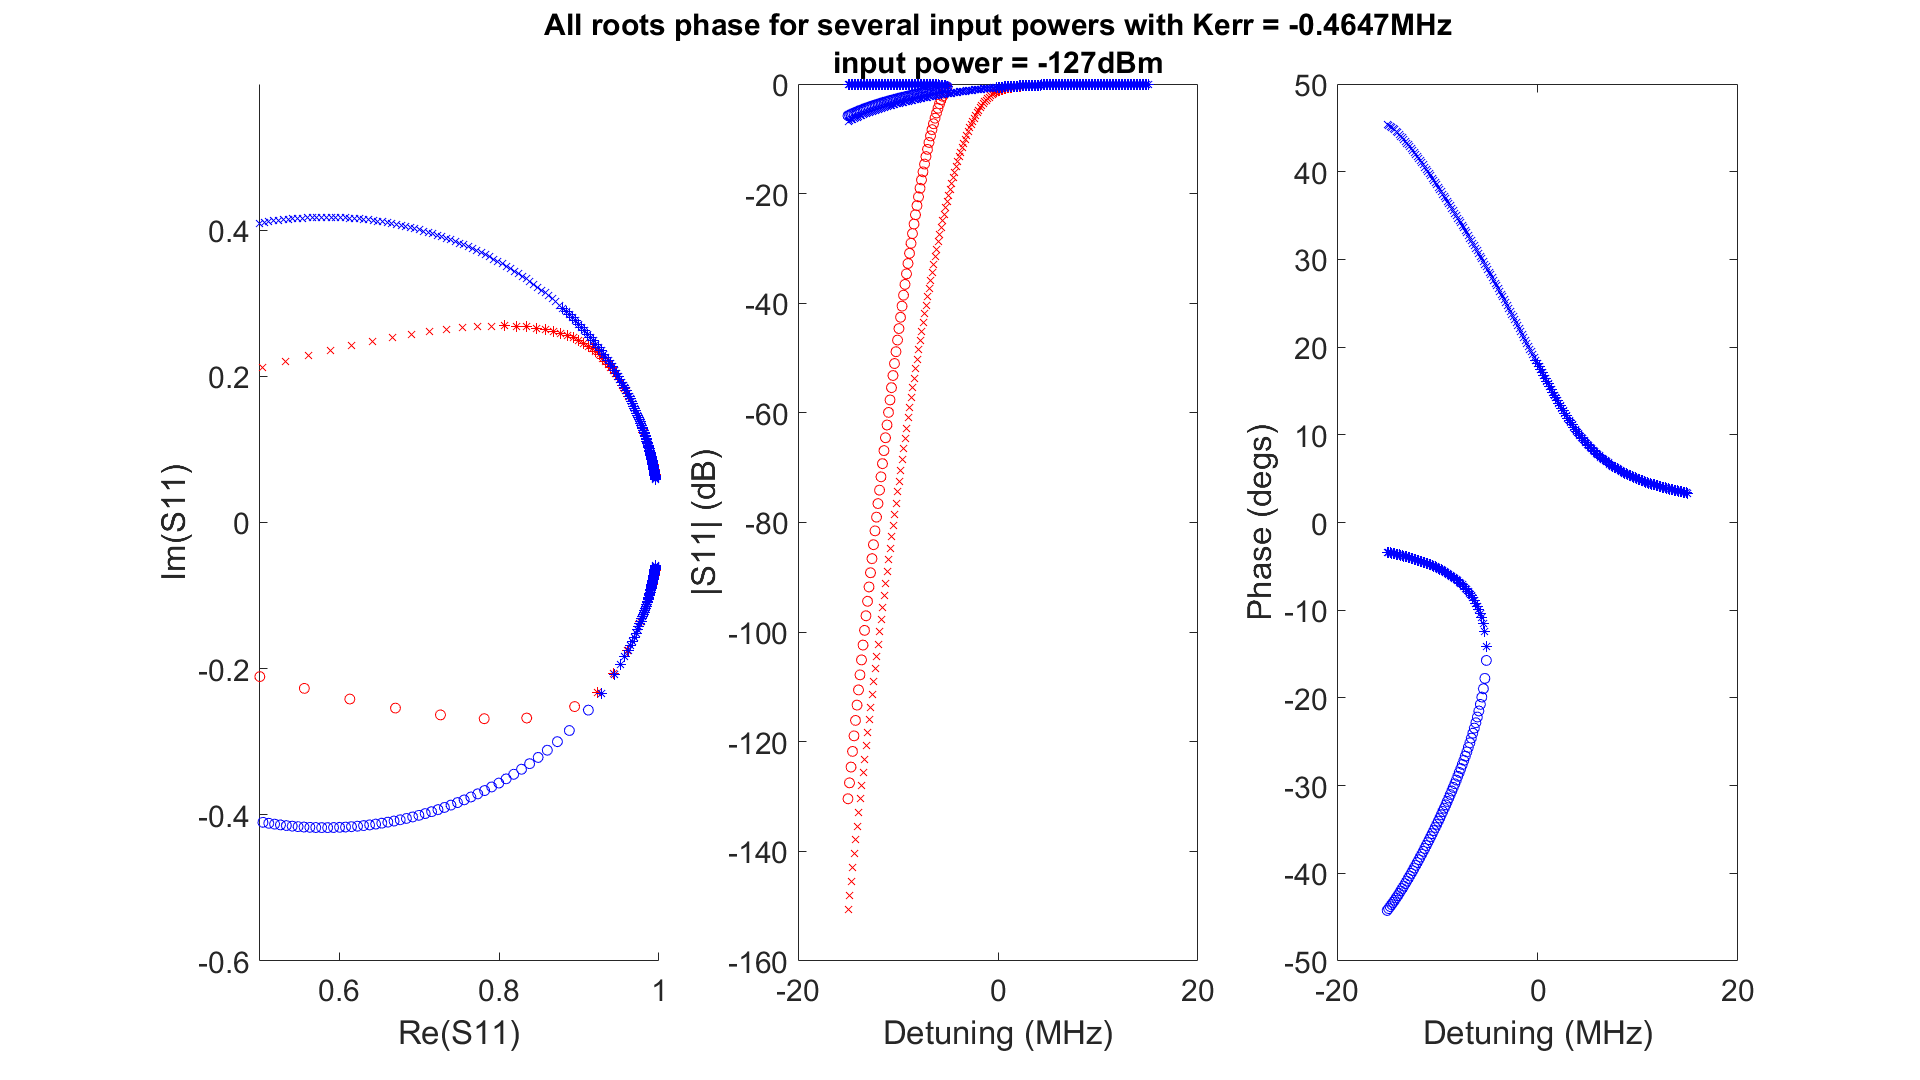

figure
subplot(1,3,3)
color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<number_powers + 1
        detunings_array_averaged = detunings_array(i,:);
        s11_averaged_root_1_temp = squeeze(kerr_averaged_s11(i,:,1));
        s11_averaged_root_2_temp = squeeze(kerr_averaged_s11(i,:,2));
        s11_averaged_root_3_temp = squeeze(kerr_averaged_s11(i,:,3));
        
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '*'];
        
        plot(detunings_array_averaged, wrapTo180(angle(s11_averaged_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        plot(detunings_array_averaged, wrapTo180(angle(s11_averaged_root_2_temp)*180/pi),root_2_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(detunings_array_averaged, wrapTo180(angle(s11_averaged_root_3_temp)*180/pi),root_3_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        j = 2;
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '*'];
        plot(detunings_array_1, wrapTo180(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(detunings_array_2, wrapTo180(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, wrapTo180(angle(s11_root_3_temp)*180/pi),root_3_color_prop)
        xlabel('Detuning (MHz)')
        ylabel('Phase (degs)')
%         title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
%     h = zeros(5,1);
%     h(1) = plot(nan, nan, 'r');hold on
%     h(2) = plot(nan, nan, 'b');
%     h(3) = plot(nan, nan, 'k');
%     h(4) = plot(nan, nan, 'g');
%     h(5) = plot(nan, nan, 'm');
%     legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
%         [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
     hold off
subplot(1,3,1)
hold on
color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<number_powers + 1
        detunings_array_averaged = detunings_array(i,:);
        s11_averaged_root_1_temp = squeeze(kerr_averaged_s11(i,:,1));
        s11_averaged_root_2_temp = squeeze(kerr_averaged_s11(i,:,2));
        s11_averaged_root_3_temp = squeeze(kerr_averaged_s11(i,:,3));
        
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '*'];

        
        plot(real(s11_averaged_root_1_temp),imag(s11_averaged_root_1_temp),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        plot(real(s11_averaged_root_2_temp),imag(s11_averaged_root_2_temp),root_2_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(real(s11_averaged_root_3_temp),imag(s11_averaged_root_3_temp),root_3_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])        
        j = 2;
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '*'];
        plot(real(s11_root_1_temp),imag(s11_root_1_temp),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(real(s11_root_2_temp),imag(s11_root_2_temp),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(real(s11_root_3_temp),imag(s11_root_3_temp),root_3_color_prop)
        xlabel('Re(S11)')
        ylabel('Im(S11)')
%         title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
%     h = zeros(5,1);
%     h(1) = plot(nan, nan, 'r');hold on
%     h(2) = plot(nan, nan, 'b');
%     h(3) = plot(nan, nan, 'k');
%     h(4) = plot(nan, nan, 'g');
%     h(5) = plot(nan, nan, 'm');
%     legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
%         [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
     hold off
     axis([.5 1 -.6 .6])
subplot(1,3,2)
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<number_powers + 1
        detunings_array_averaged = detunings_array(i,:);
        s11_averaged_root_1_temp = squeeze(kerr_averaged_s11(i,:,1));
        s11_averaged_root_2_temp = squeeze(kerr_averaged_s11(i,:,2));
        s11_averaged_root_3_temp = squeeze(kerr_averaged_s11(i,:,3));
        
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '*'];
        
        plot(detunings_array_averaged, 20*log10(abs(s11_averaged_root_1_temp)),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        plot(detunings_array_averaged, 20*log10(abs(s11_averaged_root_2_temp)),root_2_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(detunings_array_averaged, 20*log10(abs(s11_averaged_root_3_temp)),root_3_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])        
        j = 2;
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '*'];
        plot(detunings_array_1, 20*log10(abs(s11_root_1_temp)),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(detunings_array_2, 20*log10(abs(s11_root_2_temp)),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, 20*log10(abs(s11_root_3_temp)),root_3_color_prop)
        xlabel('Detuning (MHz)')
        ylabel('|S11| (dB)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz' 13 10 'input power = ' ...
            num2str(power_input_stop_dBm) 'dBm'])
        i = i + 20;
        j = j + 1;
    end
%     h = zeros(5,1);
%     h(1) = plot(nan, nan, 'r');hold on
%     h(2) = plot(nan, nan, 'b');
%     h(3) = plot(nan, nan, 'k');
%     h(4) = plot(nan, nan, 'g');
%     h(5) = plot(nan, nan, 'm');
%     legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
%         [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
     hold off